# Diffusion model 3D

tic
close all;
clear runData modelData;
runData.filename = 'testgif.gif';
runData.runType = 'time';
runData.oneGroup = true;
runData.adjointFlag = false; % --> ???
runData.checkGeometry = true;
runData.plotSolution = true;
runData.hmax = 0.2;          % mesh size, maximum edge length element: default hmax = 0.33
% Cross section settings
runData.dataset = 'Diff_driven';  
runData.group = 1;          % --> delete: group number to use for the cross-sections, must be one in this case, since only one type/group/NP (nGroups is also 1)
runData.nGroups = 1;

% Load material properties and sources
[modelData.Diff,modelData.Diff_info] = s4_loadXS_EK(runData.dataset);
% Material assignment to model domains
modelData.materialIDs = [1,2]; % define differently if different material per face (# faces = 2, so 2 elements)

% Source assignment to model domains
modelData.sourceIDs = [1,1]; % define differently if different source term (more heat /concentration)
modelData.fixedSource = [0;0]; % Source terms, is zero for both subdomains. Change if different source terms. 

### 1-3. Create PDE, geometry and Mesh

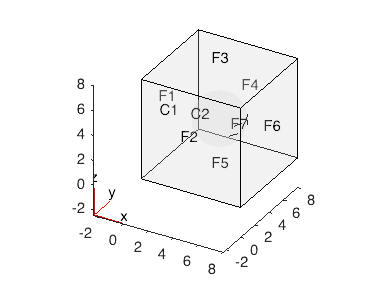

% Create PDE model
[model,modelData] = s1_createPDEModel(runData,modelData);
% Load test geometry
[model,centretumor,diametertumor] = d2_createGeometry3D(model,runData); % default = t2_creategeometry2D (circle tumor + part breast)

toc

Elapsed time is 0.435442 seconds.


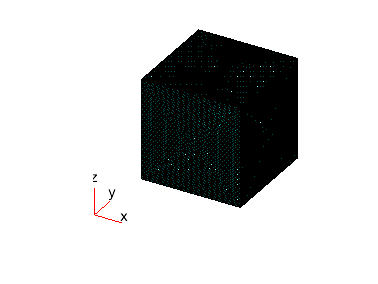


tic
% Generate mesh
[model] = d3_createMesh3D(model,runData);

toc

Elapsed time is 11.759582 seconds.


### 4-6. define BC, IC and properties

% 4. Boundary conditions 
tic
% Boundary conditions:      only applicable for outer boundaries (no information on volume outside control volume)
runData.nBCs.neumann = 1;   % necessary to define if multiple neumann boundaries with different values
runData.BCs.neumann(1) = struct('face',1:6,'q',0,'g',@BCbreast); % flux breast [#NPs/m2*s] % must depend on conc. present to not become negative. Which BC?
%runData.BCs.neumann(2) = struct('edge',[2 3],'q',0,'g',0); %6 flux tumor [#NPs/m2*s]
runData.nBCs.dirichlet = 1;
runData.BCs.dirichlet(1) = struct('face',[],'u',0);     % [] means isempty

% 5. Initial condition
% find out if time dependent or not: if not --> elliptic eq.
                                    % if    --> parabolic eq.
%modelData.SourceValue = 3.19*10^20; % #/cm3concentration of NPs per injection volume ~1.25E+12 #NPs/injection
modelData.SourceValue = 1.19*10^13*0.10 % maxiumum possible #NPs/injection; % #/injection concentration of NPs per injection volume ~1.25E+12 #NPs/injection

modelData = struct with fields:
           Diff: [1×2 struct]
      Diff_info: [1×1 struct]
    materialIDs: [1 2]
      sourceIDs: [1 1]
    fixedSource: [2×1 double]
    SourceValue: 1.1900e+12


D = 4; % diameter sphere and 
R = D/2; % radius of sphere/tumor
[X,Y,Z, noSeeds] = d3_seedlocations_cube(D);

nRows = 6


%view([60 25])
X = X + (centretumor(1)-(D+2)/2);       % correct the seed locations to the location of the tumor in the breast
Y = Y + (centretumor(2)-(D+2)/2);       % tumor cannot be larger than radius of seedfield, so always R - centretumor
Z = Z + (centretumor(3)-(D+2)/2);       % tumor cannot be larger than radius of seedfield, so always R - centretumor

modelData.x0 = X;
modelData.y0 = Y;
modelData.z0 = Z;
modelData.sigmax = 0.05;           % standard deviation: smaller --> smaller negative concentration  
modelData.sigmay = 0.05;          % ?? --> smaller value larger negative concentration
modelData.sigmaz = 0.05;          % ?? --> smaller value larger negative concentration

modelData.Cini1 = 0; % mg/ml = kg/m3: initial concentration of NPs in body
modelData.C_NP0 = @(location)Cinit_NP3D(location,modelData.x0,modelData.y0,modelData.z0,modelData.sigmax,modelData.sigmay,modelData.sigmaz,modelData.SourceValue); % mg/ml = kg/m3: concentration of NPs in seeds
runData.nICs = 2;                  % necessary to define if multiple initial conditions different per face
runData.IC(1) = struct('u',modelData.Cini1,'Cell',1);
runData.IC(2) = struct('u',modelData.C_NP0,'Cell',2);

[model] = d4_loadBCIC(model,modelData,runData);
toc

Elapsed time is 0.252907 seconds.



% time scale
h = 24*17*2; % number of hours
runData.timePoints = 0:3:h; % times at which to compute a solution specified in the array tlist
                    % between 0 and 60 minutes in steps of 60 secs                 

### 6. solve PDE system

tic
% Solve PDE model (including properties)
[~,results] = s5_NPDiffusion2D(model,modelData,runData);
toc

Elapsed time is 5880.137725 seconds.


T = results.NodalSolution;


solMax = max(T)

solMax = 1.0e+12 *

    1.1900    1.2381    1.2744    1.3030    1.3245    1.3399    1.3500    1.3558    1.3579    1.3587    1.3596    1.3583    1.3548    1.3495    1.3426    1.3343    1.3249    1.3144    1.3031    1.2916    1.2824    1.2725    1.2639    1.2556    1.2468    1.2378    1.2284    1.2189    1.2091    1.1991    1.1890    1.1788    1.1685    1.1581    1.1476    1.1422    1.1369    1.1315    1.1261    1.1206    1.1150    1.1093    1.1036    1.0978    1.0920    1.0861    1.0802    1.0743    1.0683    1.0623


solMin = min(T)

solMin = 1.0e+10 *

         0   -3.7896   -6.3829   -8.0324   -8.9413   -9.2734   -9.1601   -8.7068   -8.0612   -8.2383   -8.3039   -8.2736   -8.1609   -7.9778   -7.7348   -7.4409   -7.1039   -6.7308   -6.3275   -5.8992   -5.6885   -5.5380   -5.3637   -5.1683   -4.9764   -4.9115   -4.8329   -4.7419   -4.6396   -4.5268   -4.4045   -4.2736   -4.1348   -3.9889   -3.8365   -3.6782   -3.5146   -3.3463   -3.1810   -3.1168   -3.0444   -2.9643   -2.8769   -2.7827   -2.6819   -2.5750   -2.4623   -2.3443   -2.2212   -2.0934


## Three diffusion plots in time

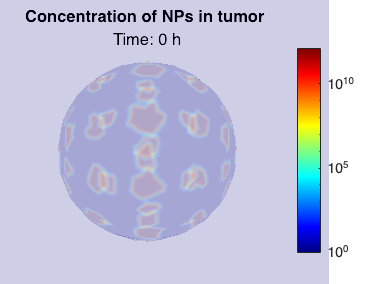

a = 1; b = 136; c = 273;

pdeplot3D(model,"ColorMapData",T(:,a),'FaceAlpha',0.1);
xlim([2.3 5.7]);
ylim([2.3 5.7]);
zlim([2.3 5.7]);
%caxis([0 3*10^20]);
set(gca,'ColorScale','log')
caxis([10^0 1.19*10^12]);
title('Concentration of NPs in tumor ','Time: 0 h');
% colorbar('YTick',log(c),'YTickLabel',c);al 
%axis on
view([90 67.5])

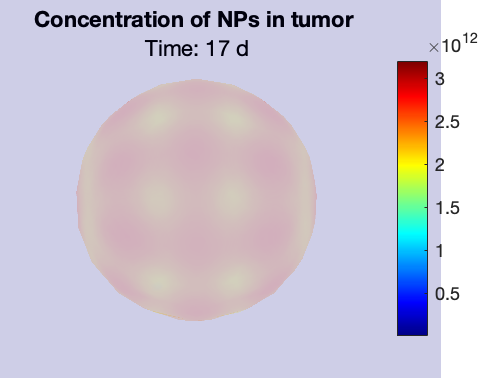


pdeplot3D(model,"ColorMapData",T(:,b),'FaceAlpha',0.1);
xlim([2.3 5.7]);
ylim([2.3 5.7]);
zlim([2.3 5.7]);
set(gca,'ColorScale','log')
%caxis([(min(solMin)) (max(solMax))]);
caxis([10^7 3.19*10^12]);
title('Concentration of NPs in tumor ','Time: 17 d');
%axis on
view([90 67.5])

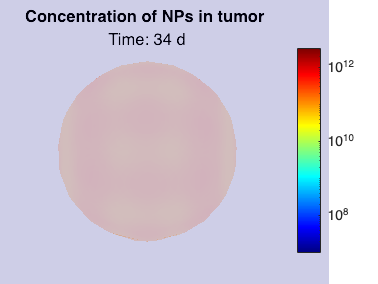


pdeplot3D(model,"ColorMapData",T(:,c),'FaceAlpha',0.1);
xlim([2.3 5.7]);
ylim([2.3 5.7]);
zlim([2.3 5.7]);
set(gca,'ColorScale','log')
%caxis([(min(solMin)) (max(solMax))]);
caxis([10^7 3.19*10^12]);
title('Concentration of NPs in tumor ','Time: 34 d');
%axis on
view([90 67.5])

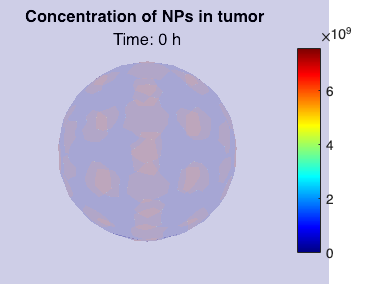



pdeplot3D(model,"ColorMapData",T(:,a),'FaceAlpha',0.1);
xlim([2.3 5.7]);
ylim([2.3 5.7]);
zlim([2.3 5.7]);
%caxis([0 3*10^20]);
%set(gca,'ColorScale','log')
caxis([0 7.53*10^9]);
title('Concentration of NPs in tumor ','Time: 0 h');
% colorbar('YTick',log(c),'YTickLabel',c);
%axis on
view([90 67.5])

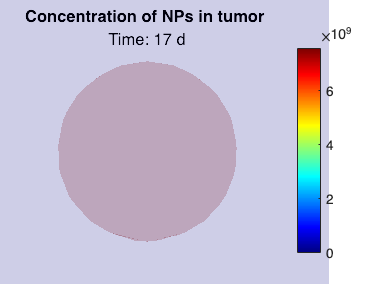


pdeplot3D(model,"ColorMapData",T(:,c),'FaceAlpha',0.1);
xlim([2.3 5.7]);
ylim([2.3 5.7]);
zlim([2.3 5.7]);
%set(gca,'ColorScale','log')
%caxis([(min(solMin)) (max(solMax))]);
caxis([0 7.53*10^9]);
title('Concentration of NPs in tumor ','Time: 17 d');
%axis on
view([90 67.5])


% pdeplot3D(model,"ColorMapData",T(:,b),'FaceAlpha',0.1);
% xlim([2 6]);
% ylim([2 6]);
% zlim([2 6]);
% %set(gca,'ColorScale','log')
% %caxis([(min(solMin)) (max(solMax))]);
% caxis([0 7.53*10^9]);
% title('Concentration of NPs in tumor ','Time: 12 h');
% axis on
% view([90 67.5])


## Diffusion plots over time

solMin = -9.2734e+10

solMax = 1.3596e+12

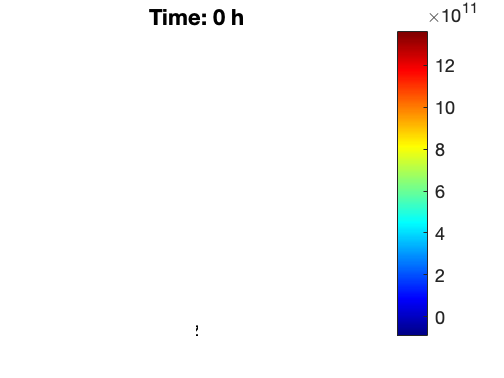

Error using s7_gif
The giffing has been canceled.

Error in d6_plotPDESolution3D (line 31)
                        s7_gif(runData.filename,'DelayTime',0.2,'frame',gcf);

d6_plotPDESolution3D(model,T,runData) %% --> not yet fixed for 3D


% for i = 0:4
%     for j = 1:4 
%         figure(i+1);
%         subplot(2,2,j);
%         pdeplot3D(model,"ColorMapData",T(:,((1+(j-1)+(4*i)))),'FaceAlpha',0.1);
%         xlim([0 20]);
%         ylim([0 20]);
%         zlim([-20 0]);
%         caxis([0 C(1,1)]);
%         title(['Temperature at time =', num2str((1+(j-1)+(4*i))*3*min),' min'])
%         axis on
%     end
% end

### Initial condition function

function Cinit_tumor = Cinit_NP3D(location,x0,y0,z0,sigmax,sigmay,sigmaz,SourceValue)
        % heaviside gives 0 if the equation of radius - the circle is smaller than 0 (location is outside the circle)
        % and gives 1*Sourcevalue for all locations within the circle
        % third term represents a normal distribution over x and y, resulting in a smooth distribution
        % with the coordinations of the node as the maximum of the Gaussian peak (=1).
        % This needs to be multiplid with the value of the concentration of the injection
        r = 0.2;            % radius that the seed should have
        R = 3*r^2;      % radius of heaviside circle        
        Cinit_tumor = 0;
        for i = 1:length(x0)
        Cinit_seed = (heaviside(R- ( (location.x-x0(i)).^2 + (location.y-y0(i)).^2 + (location.z-z0(i)).^2) ) ) .*SourceValue; % .*exp( -( (location.x-x0(i)).^2 ./ sigmax^2 ) -( (location.y-y0(i)).^2 ./ sigmay^2) -( (location.z-z0(i)).^2 ./ sigmaz^2) ); 
        Cinit_tumor = Cinit_tumor + Cinit_seed;
        end        
end

% function Cinit_tumor = Cinit_NP3D(location,X,Y,Z,sigmax,sigmay,sigmaz,SourceValue)
%         % heaviside gives 0 if the equation of radius - the circle is smaller than 0 (location is outside the circle)
%         % and gives 1*Sourcevalue for all locations within the circle
%         % third term represents a normal distribution over x and y, resulting in a smooth distribution
%         % with the coordinations of the node as the maximum of the Gaussian peak (=1).
%         % This needs to be multiplied with the value of the concentration of the injection
%         Cinit_tumor = 0;
%         Cinit_tumorslicey = 0;
%         Cinit_tumorslicexy = 0;
%         for slice = 1:length(X(:,1))
%             for x0 = 1:length(X(:,1))
%                 for y0 = 1:length(X(:,1))
%                 Cinit_seed = (heaviside(0.3- ( (location.x-X(x0,y0,slice)).^2 + (location.y-Y(x0,y0,slice)).^2 + (location.z-Z(x0,y0,slice)).^2) ) ) .*SourceValue .*exp( -( (location.x-X(x0,y0,slice)).^2 ./ sigmax^2 ) -( (location.y-Y(x0,y0,slice)).^2 ./ sigmay^2) -( (location.z-Z(x0,y0,slice)).^2 ./ sigmaz^2) ); 
%                 Cinit_tumorslicey = Cinit_tumorslicey + Cinit_seed;
%                 end  
%             Cinit_tumorslicexy = Cinit_tumorslicexy + Cinit_tumorslicey;
%             end
%             Cinit_tumor = Cinit_tumor + Cinit_tumorslicexy;
%         end
% end

function bcbreast = BCbreast(~,state)        % function for boundary condition at body
    bcbreast = state.u*1.63*10^(-8)*60*60;  % cm2/h
end



% function fcoef_tumor = fcoef_PS(location,~,nPointSources,PointSources,SourceValue)
% 
% fcoef_tumor = zeros(1,length(location.x));
%     for l = 1:nPointSources
%         for i = 1:numel(fcoef_tumor) 
%                 if location.x == PointSources(l,1) & location.y == PointSources(l,2) & location.z == PointSources(l,3)
%                     indexX = find(location.x(:) == PointSources(l,1));
%                     indexY = find(location.y(:) == PointSources(l,2));
%                     indexZ = find(location.z(:) == PointSources(l,3));
%                     indicesXY = intersect(indexX,indexY);
%                     indicesXYZ = intersect(indicesXY,indexZ);
%                     fcoef_tumor(1,indicesXYZ) = SourceValue;
%                 end
%         end
%     end
%     fcoef_tumor
% end
% 